%https://www.mathworks.com/content/dam/mathworks/tag-team/Objects/c/88360_93001v00_Color-Based_Seg_K-Means_Clustering_2016.pdf

addpath('databas2')
allSize = 7128;
database = cell(1,allSize);
numberOfCluster = 50;

for i = 1:size(database,2)
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    database{i} = img;
end

allChannels = zeros(3,allSize)

allChannels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


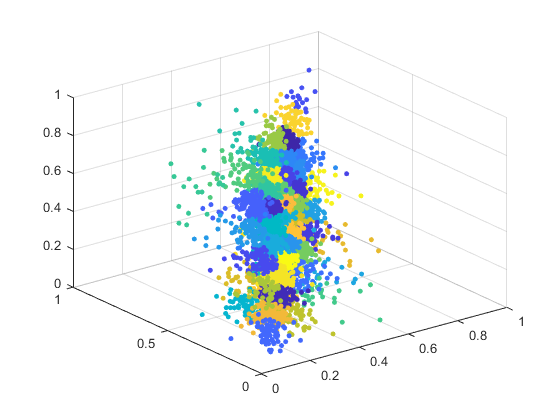


for i = 1:allSize
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    allChannels(1,i) = mean(mean(img(:, :, 1)));
    allChannels(2,i) = mean(mean(img(:, :, 2)));
    allChannels(3,i) = mean(mean(img(:, :, 3)));
end
X = allChannels';
[idx,C] = kmeans(X,numberOfCluster);

% plot 3D clusters
scatter3(X(:,1),X(:,2),X(:,3),15,idx,'filled')


% go through all clusters in 'idx' 
cellOfCluster = cell(numberOfCluster, allSize);

% Yttre loopen går igenom alla siffror 1 till allSize
for row = 1:allSize
    col = 1;
    % Inre loopen ska gå igenom alla idx värden för att hitta match
    for i = 1:allSize
        % idx(i,1) borde vara "gruppvärdet" som dess 'id' tillhör
        if idx(i,1) == row
            cellOfCluster(row,col) = database(1,i);
            col = col + 1;
        end
    end
end

smallDatabase = cell(1,numberOfCluster*4);

smallDatabase(1,1:50) = cellOfCluster(:,1)';
smallDatabase(1,51:100) = cellOfCluster(:,2)';
smallDatabase(1,101:150) = cellOfCluster(:,3)';
smallDatabase(1,151:200) = cellOfCluster(:,4)';

% for i = 1:10
%     figure
%     imshow(cell2mat(smallDatabase(1,i)))
% end

% for i = 1:200
%     imresize()
% end








% cluster1 = cell(1,allSize);
% cluster2 = cell(1,allSize);
% cluster3 = cell(1,allSize);

% Go through all clusters and seperate them into each array
% for i = 1:allSize
%     if idx(i,1) == 1
%         cluster1(i) = database(1,i);
%     end
%     if idx(i,1) == 2
%         cluster2(i) = database(1,i);
%     end
%     if idx(i,1) == 3
%         cluster3(i) = database(1,i);
%     end
% end

% Remove empty cells
% cluster1(:, any(cellfun(@isempty, cluster1), 1)) = [];
% cluster2(:, any(cellfun(@isempty, cluster2), 1)) = [];
% cluster3(:, any(cellfun(@isempty, cluster3), 1)) = [];






Beräkna medelvärdet på alla cluster, behövs ej nu

% meanClus1 = 0;
% meanClus2 = 0;
% meanClus3 = 0;
% 
% for i = 1:size(cluster1(2))
%     lab1 = rgb2lab(cell2mat(cluster1(i)));
%     meanClus1 = meanClus1 + mean(mean(lab1));
% end
% for i = 1:size(cluster2(2))
%     lab2 = rgb2lab(cell2mat(cluster2(i)));
%     meanClus2 = meanClus2 + mean(mean(lab2));
% end
% for i = 1:size(cluster3(2))
%     lab3 = rgb2lab(cell2mat(cluster3(i)));
%     meanClus3 = meanClus3 + mean(mean(lab3));
% end
% 
% meanClus1 = meanClus1/size(cluster1(1,2),2)
% meanClus2 = meanClus2/size(cluster2(1,2),2)
% meanClus3 = meanClus3/size(cluster3(1,2),2)
